# Disturbance Observation

**also called a model regulator**

a Robust Controls method applied to Mechatronic Systems

By Brian Lesko, 

Graduate Researcher and Teaching Associate, Masters of mechanical engineering student 

Robust Controls 8352 | Ohio State University | 11/13/2022

with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc

## Previous work 

    The Qube servo plant used in this demonstrstion has been studied previously. During this previous work, time and frequency responses have been documented when implementing a variety of controller design methods. First, D-stability, margin bounds, and mixed sensitivity were used to achieve a multi-objective design by producing a controller parameter space. Next, analytical methods were used to produce a lead-lag and then PID controller - where the same procedures were repeated for numerous increases in the plant time constant. 

## Controls Background

    Disturbance observation or Model regulation is a 2 DOF method that achieves insensitivity against modeling erros. Modeling erros are common due to order reduction, linearization, and parameter uncertainties. The disturbance observer, in addition to aiding modeling error, rejects disturbances within its bandwidth of operation. 

Disturbance Observer

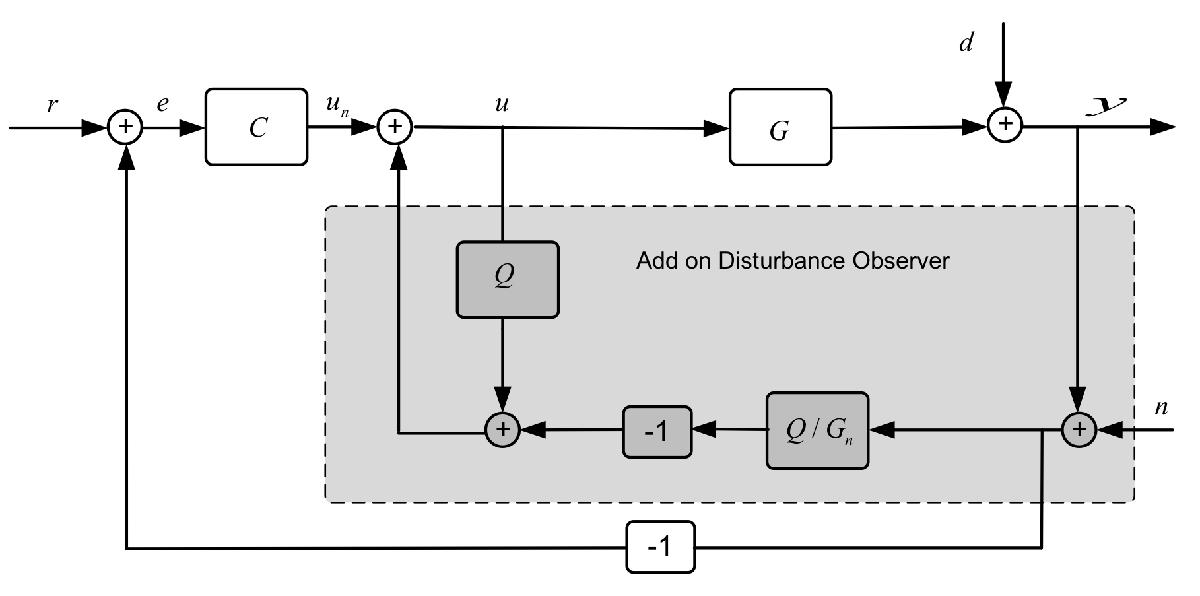

%The Nominal Plant
s = tf('s'); tau_n = 0.1; K_n = 28;
Gn = K_n / (tau_n*s + 1) % / s for the angular position plant

Gn =
 
     28
  ---------
  0.1 s + 1
 
Continuous-time transfer function.



% 25% increase in parameters, "Unexpected" Actual Plant
increase = 1.12;
K = K_n * increase; 
tau = tau_n * increase; 
tau_d = 0;
G = K / (tau*s + 1) * exp(tau_d * s); %%%
uncertainty_bound = Gn/(G-Gn);

% Low pass unity gain
Qnum = 0.03 * s + 1; Qden = (0.01)^3*s^3 + 3*(0.01)^2*s^2 + 0.03*s + 1; 
Q = Qnum / Qden;

% Controller
C = (1.122*s + 1)/(9.238*10^-5 + 1); % A Lead Controller from Previous Work

# Disturbance Rejection

y_d = Gn*(1-Q)/(Gn*(1-Q)+G*Q); % disturbance rejection, no controller
disturbanceRejection(y_d,G)

# Command Following 

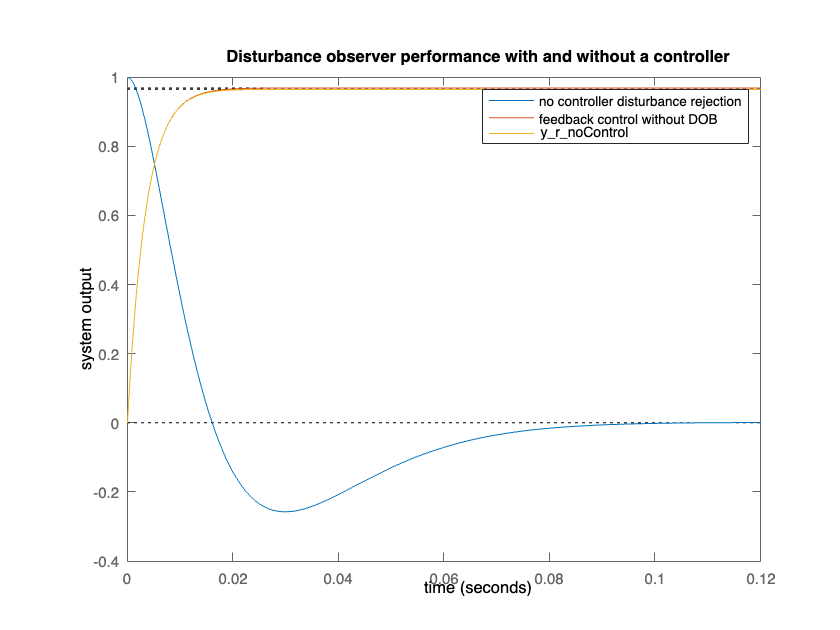

C=1; y_r_noControl = C*Gn*G/(Gn*(1-Q)+G*(C*Gn+Q));
step(y_r_noControl)

# Frequency Domain Magnitude Responses

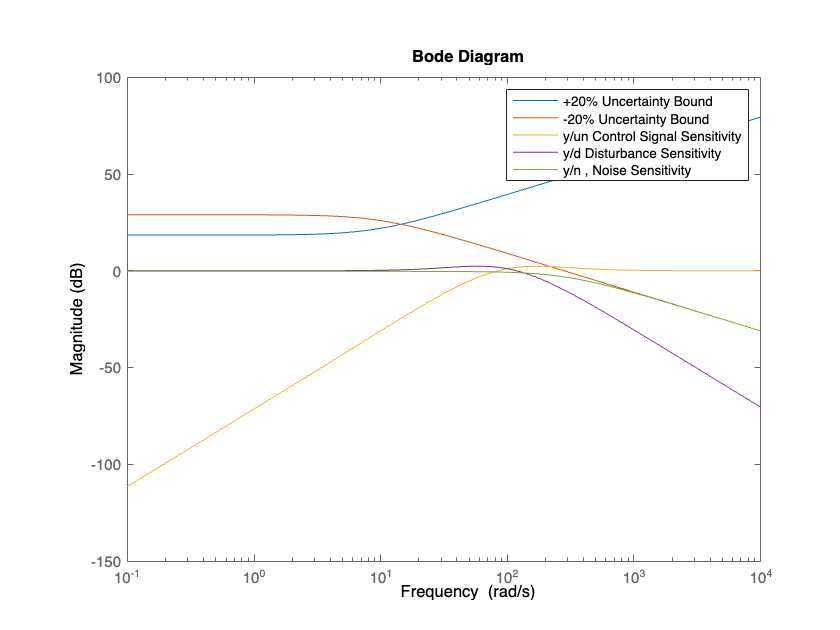

magResponse(G,Gn,Q,C)

# Functions

function magResponse(G,Gn,Q,C)
    uncertainty_bound = Gn/(G-Gn);
    %Sensitivity Responses 
    y_un = Gn*G / (Gn*(1-Q)+G*Q); % model regulation - un is the control signal 
    y_d = Gn*(1-Q)/(Gn*(1-Q)+G*Q); % disturbance rejection
    y_n = -G*Q/(Gn*(1-Q)+G*Q); % sensor noise rejection
    y_r = C*Gn*G/(Gn*(1-Q)+G*(C*Gn+Q)); %input output sensitivty 
    y_un = minreal(y_un);
    y_d = minreal(y_d);
    y_n = minreal(y_n);

    figure()
    hold on
    bodemag(uncertainty_bound); bodemag(y_un); bodemag(y_d); bodemag(y_n); bodemag(y_r)
    legend('+20% Uncertainty Bound','-20% Uncertainty Bound','y/un Control Signal Sensitivity','y/d Disturbance Sensitivity','y/n , Noise Sensitivity','y/r Input Signal Sensitivity')
    hold off
end 

function disturbanceRejection(y_d,G)
    figure()
    hold on
    step(y_d)
    step(G*(1-feedback(G,1))) % No disturbance observer with feedback control 
    legend('no controller disturbance rejection','feedback control without DOB')
    title('Disturbance observer performance with and without a controller')
    xlabel('time'), ylabel('system output')
end 